Question 1

a) For around the first 15 t values, the y vs. t graph looks to show a trend. It can be described as a sideways funnel, but as t increases, the results become less uniform and more erratic.

b) The z vs. x graph appears to have a pattern. It can be defined as a spiral, however like with the preceding graph, as t increases, the results become less uniform and erratic. 

c) The x vs. y vs. z graph appears to have a pattern at first, but after a while, it abruptly changes altogether. Initially, it looked to produce a graph looking like a leaf. However, as t increases, a new graph with a different leaf appears, becoming less uniform and erratic. 

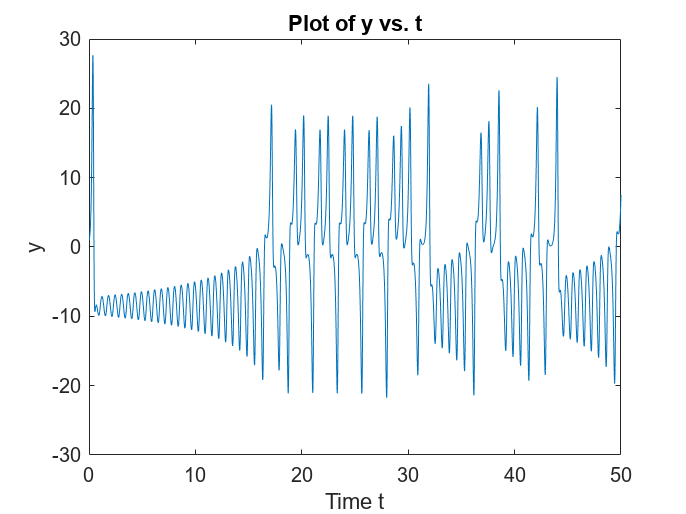

%1
sig = 10;
b = 8/3;
r = 28;
lorenz = @(t, X) [sig * (X(2) - X(1)); 
                  r * X(1) - X(2) - X(1) * X(3); 
                  X(1) * X(2) - b * X(3)];

X0 = [0; 1; 0];
tspan = [0 50];
[t, X] = ode45(lorenz, tspan, X0);

%a
figure;
plot(t, X(:,2));
title('Plot of y vs. t');
xlabel('Time t');
ylabel('y');

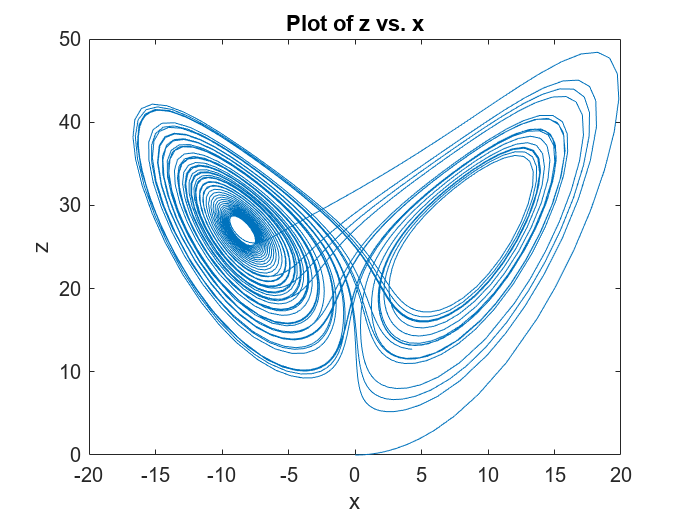


%b
figure;
plot(X(:,1), X(:,3));
title('Plot of z vs. x');
xlabel('x');
ylabel('z');

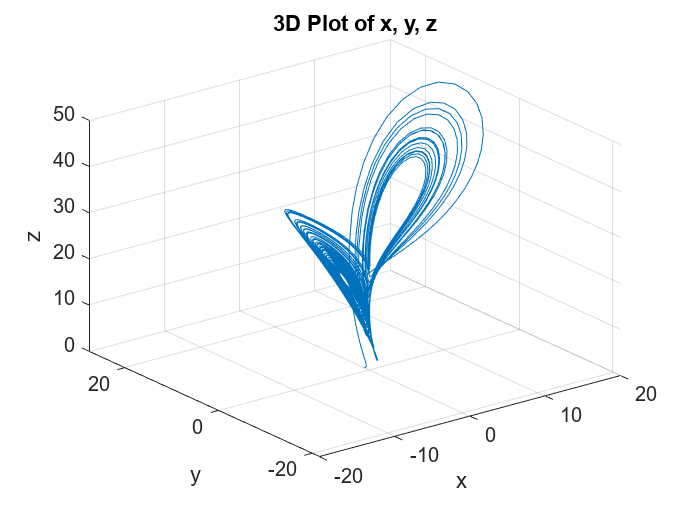


%c
figure;
plot3(X(:,1), X(:,2), X(:,3));
title('3D Plot of x, y, z');
xlabel('x');
ylabel('y');
zlabel('z');
grid on;

Question 2

With slightly different initial conditions, the graph appears to begin identically, but as t advances, they both exhibit distinct and erratic patterns. Nonetheless, the results appear to be in the same ranges, but they differ. A tiny adjustment in initial conditions could influence the graph in this way due to the system's complexity. Because the system is affected by three variables and dimensions, even minor changes have far-reaching and unforeseen consequences. A value of 0 cancels out some terms at the beginning of the system's operation, whereas an initial value that is no longer 0 may have immediate consequences on the systems. 

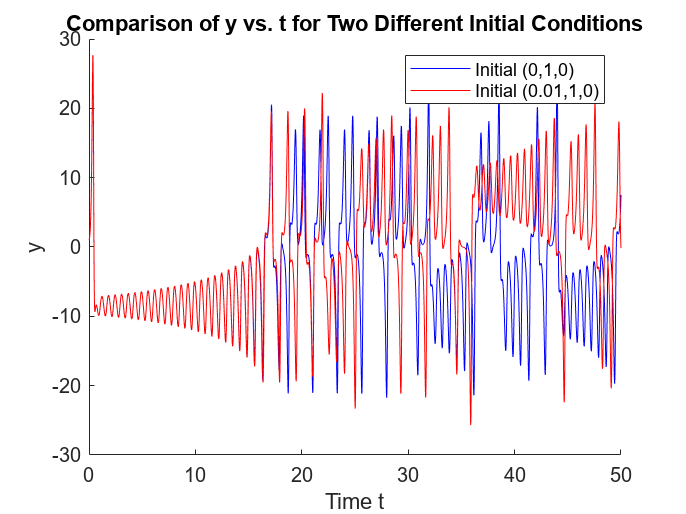

%2
X0_new = [0.01; 1; 0];
[t_new1, X_new1] = ode45(lorenz, tspan, X0_new);

figure;
hold on;
plot(t, X(:,2), 'b');
plot(t_new1, X_new1(:,2), 'r');
title('Comparison of y vs. t for Two Different Initial Conditions');
xlabel('Time t');
ylabel('y');
legend('Initial (0,1,0)', 'Initial (0.01,1,0)');

Question 3

Work:

x=y, z=xy/b�, 0=rx−y−x^2*y/b -->�

0=rx−x−x^3/b

x^2=(r−1)*b,y=x,z=x^2/b�

(x,y,z)=(±sqrt(b(r−1))�,±sqrt(b(r−1))�,(r−1)�)�

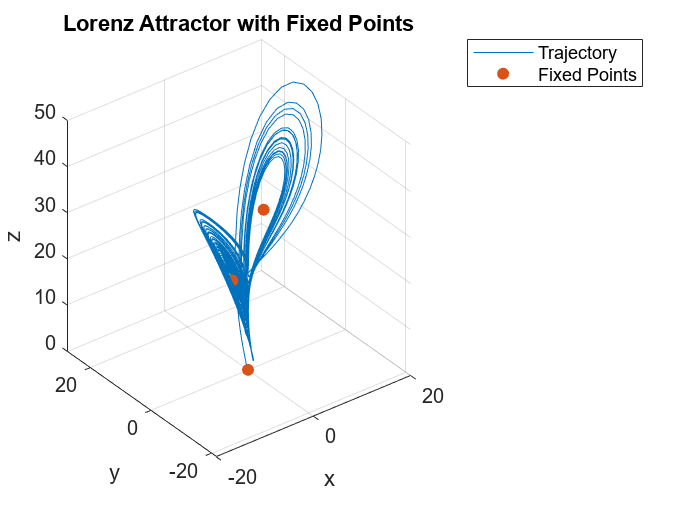

%3
fixed_points = [0 0 0; sqrt(b*(r-1)) sqrt(b*(r-1)) r-1; -sqrt(b*(r-1)) -sqrt(b*(r-1)) r-1];
figure;
plot3(X(:,1), X(:,2), X(:,3));
hold on;
scatter3(fixed_points(:,1), fixed_points(:,2), fixed_points(:,3), 'filled');
title('Lorenz Attractor with Fixed Points');
xlabel('x');
ylabel('y');
zlabel('z');
legend('Trajectory', 'Fixed Points');
grid on;

Question 4

J=[�−σ    σ    0;

    r−z    −1    −x;

    y    x    −b]

det(J−λI) = 0 =

    [�−σ−λ    σ    0;

    r−z    −1−λ    −x;

    y    x    −b−λ]

Fixed points:

- [0, 0, 0]

- [sqrt(b*(r-1)), sqrt(b*(r-1)), r-1] ~= 8.4853, 8.4853, 27

- [-sqrt(b*(r-1)), -sqrt(b*(r-1)) r-1] ~=  -8.4853, -8.4853, 27

det(J - λI) = (−σ−λ)*((−1−λ)*(−b−λ)−(−x)*x)−σ*((r−z)(−b−λ)−(−x)*y)= λ^3 + (σ + b + 1)λ^2 + (r + σ)bλ + 2bσ(r − 1) = 0

%4
syms x y z
J_sym = [-sig, sig, 0; 
         r-z, -1, -x; 
         y, x, -b];
J_fixed = subs(J_sym, [x, y, z], [sqrt(b*(r-1)), sqrt(b*(r-1)), (b*(r-1))/b]);

syms lambda
char_eqn = det(J_fixed - lambda * eye(3));

char_eqn_simplified = simplify(char_eqn);
disp('Characteristic Equation:')

Characteristic Equation:


disp(char_eqn_simplified)

$$-\lambda^{3}-\frac{41\,\lambda^{2}}{3}-\frac{304\,\lambda }{3}-1440$$


eigenvalues = solve(char_eqn_simplified == 0, lambda);

disp('Eigenvalues:')

Eigenvalues:


disp(eigenvalues)

$$\left(\begin{array}{c} \mathrm{root}\left(z^{3}+\frac{41\,z^{2}}{3}+\frac{304\,z}{3}+1440,z,1\right)\\ \mathrm{root}\left(z^{3}+\frac{41\,z^{2}}{3}+\frac{304\,z}{3}+1440,z,2\right)\\ \mathrm{root}\left(z^{3}+\frac{41\,z^{2}}{3}+\frac{304\,z}{3}+1440,z,3\right) \end{array}\right)$$

Question 5

The trajectories from before are significantly different from those with a r value of 28. Using a r value lower than the r_H value, it made the findings more uniform and less erratic. But still, they encountered a curved spiral from the rest of the graph, but in a smaller erratic manner. It is also worth noting that both initial conditions had the same effect on the y vs t graphs. Additionally, this graph displayed the same behavior in terms of the system's fixed points. With the new r value, it seems that this system becomes less reasonable.

%5
r_H = sig * (sig + b + 3) / (sig - b - 1);
disp('r_H:')

r_H:


disp(r_H)

   24.7368



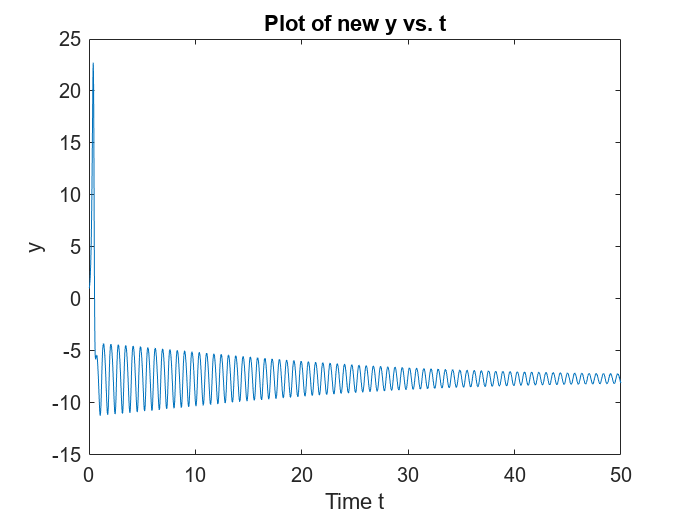


% Choice of new r < r_H
r_new = 23;

lorenz_new = @(t, X) [sig * (X(2) - X(1)); 
                      r_new * X(1) - X(2) - X(1) * X(3); 
                      X(1) * X(2) - b * X(3)];

[t_new2, X_new2] = ode45(lorenz_new, tspan, X0);

%5-1a
figure;
plot(t_new2, X_new2(:,2));
title('Plot of new y vs. t');
xlabel('Time t');
ylabel('y');

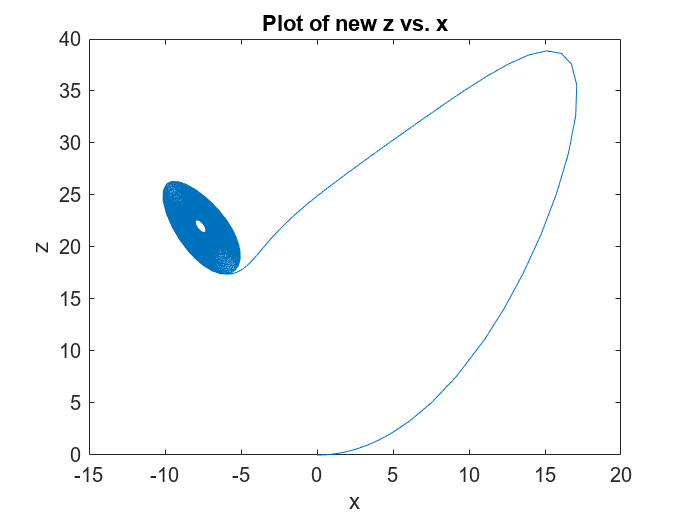


%5-1b
figure;
plot(X_new2(:,1), X_new2(:,3));
title('Plot of new z vs. x');
xlabel('x');
ylabel('z');

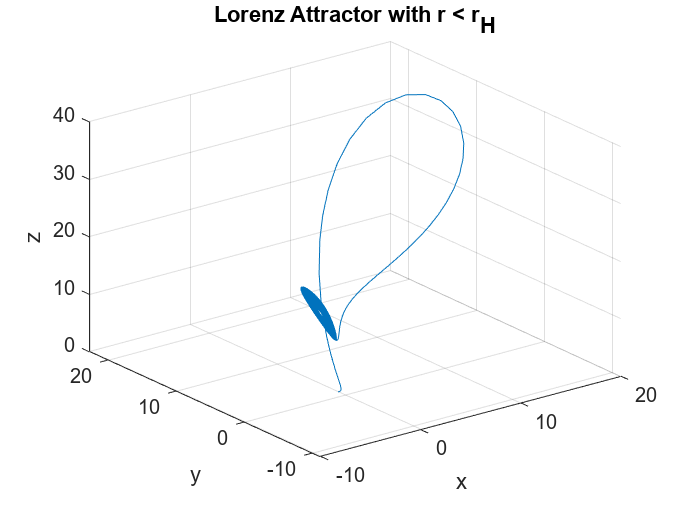


%5-1c
figure;
plot3(X_new2(:,1), X_new2(:,2), X_new2(:,3));
title('Lorenz Attractor with r < r_H');
xlabel('x');
ylabel('y');
zlabel('z');
grid on;

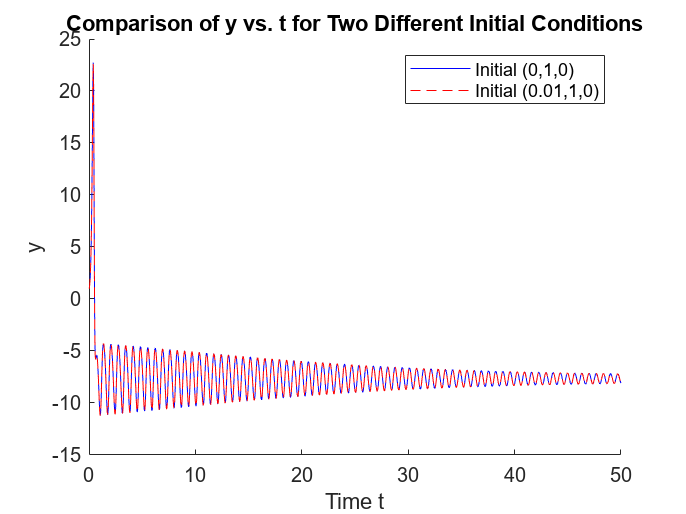


%5-2
X0_new = [0.01; 1; 0];
[t_new3, X_new3] = ode45(lorenz_new, tspan, X0_new);

figure;
hold on;
plot(t_new2, X_new2(:,2), 'b-');
plot(t_new3, X_new3(:,2), 'r--');
title('Comparison of y vs. t for Two Different Initial Conditions');
xlabel('Time t');
ylabel('y');
legend('Initial (0,1,0)', 'Initial (0.01,1,0)');

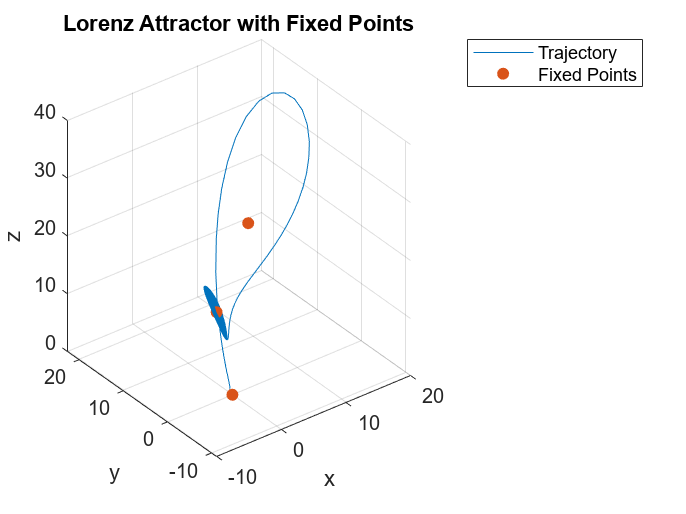


%5-3
fixed_points = [0 0 0; sqrt(b*(r_new-1)) sqrt(b*(r_new-1)) r_new-1; -sqrt(b*(r_new-1)) -sqrt(b*(r_new-1)) r_new-1];
figure;
plot3(X_new2(:,1), X_new2(:,2), X_new2(:,3));
hold on;
scatter3(fixed_points(:,1), fixed_points(:,2), fixed_points(:,3), 'filled');
title('Lorenz Attractor with Fixed Points');
xlabel('x');
ylabel('y');
zlabel('z');
legend('Trajectory', 'Fixed Points');
grid on;